# Introduction

mdl = "IngenuityExperiment";
open_system(mdl);

omega = [1 3 10 30 100];
D = [1 3 10 30 100]*0.01;
[omega_mat, D_mat] = ndgrid(omega,D)

omega_mat =      1     1     1     1     1
     3     3     3     3     3
    10    10    10    10    10
    30    30    30    30    30
   100   100   100   100   100


D_mat =     0.0100    0.0300    0.1000    0.3000    1.0000
    0.0100    0.0300    0.1000    0.3000    1.0000
    0.0100    0.0300    0.1000    0.3000    1.0000
    0.0100    0.0300    0.1000    0.3000    1.0000
    0.0100    0.0300    0.1000    0.3000    1.0000


Nsim = numel(D_mat);
simin = Simulink.SimulationInput(mdl);
for k = 1:Nsim
    hws = get_param(bdroot, 'ModelWorkspace');
    hws.assignin('Omega',omega_mat(k));
    hws.assignin('D_rotor',D_mat(k));
    simout = sim(simin, 'ShowSimulationManager', 'off', 'UseFastRestart', 'on');
    F(k) = simout.logsout{1}.Values.Data;
    pi_1(k) = F(k)/(D_mat(k)^4*omega_mat(k)^2*1.2);
    pi_2(k) = 9.81/(D_mat(k)*omega_mat(k)^2);
    pi_3(k) = 1.6/(D_mat(k)^3*1.2);
end

[22-Mar-2023 09:38:51] Running simulations...
[22-Mar-2023 09:38:51] Completed 1 of 1 simulation runs
[22-Mar-2023 09:38:52] Running simulations...
[22-Mar-2023 09:38:52] Completed 1 of 1 simulation runs
[22-Mar-2023 09:38:52] Running simulations...
[22-Mar-2023 09:38:52] Completed 1 of 1 simulation runs
[22-Mar-2023 09:38:52] Running simulations...
[22-Mar-2023 09:38:52] Completed 1 of 1 simulation runs
[22-Mar-2023 09:38:53] Running simulations...
[22-Mar-2023 09:38:53] Completed 1 of 1 simulation runs
[22-Mar-2023 09:38:53] Running simulations...
[22-Mar-2023 09:38:53] Completed 1 of 1 simulation runs
[22-Mar-2023 09:38:53] Running simulations...
[22-Mar-2023 09:38:54] Completed 1 of 1 simulation runs
[22-Mar-2023 09:38:54] Running simulations...
[22-Mar-2023 09:38:54] Completed 1 of 1 simulation runs
[22-Mar-2023 09:38:54] Running simulations...
[22-Mar-2023 09:38:54] Completed 1 of 1 simulation runs
[22-Mar-2023 09:38:54] Running simulations...
[22-Mar-2023 09:38:55] Completed 1 o

ExperimentResult = table(omega_mat(:),D_mat(:),F(:))

ExperimentResult = 25×3 table
    Var1    Var2       Var3   
    ____    ____    __________
      1     0.01    6.5973e-10
      3     0.01    5.9376e-09
     10     0.01    6.5973e-08
     30     0.01    5.9376e-07
    100     0.01    6.5973e-06
      1     0.03    5.3438e-08
      3     0.03    4.8095e-07
     10     0.03    5.3438e-06
     30     0.03    4.8095e-05
    100     0.03    0.00053438
      1      0.1    6.5973e-06
      3      0.1    5.9376e-05
     10      0.1    0.00065973
     30      0.1     0.0059376
    100      0.1      0.065973
      1      0.3    0.00053438

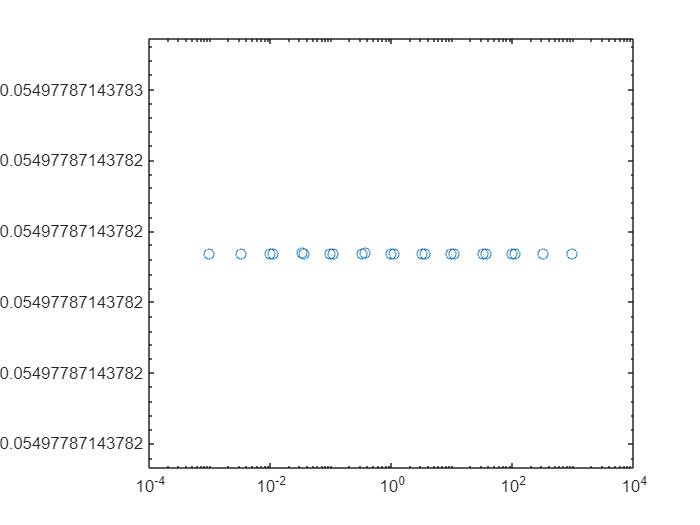

figure
loglog(pi_2,pi_1,'o')